# Note 4: Linear DDM

In this note, we review domain decomposition for a linear PDE. 

The goal is to learn how use overlapping domain decomposition as a preconditioner for a Krylov solver. 

clear

## Problem

Consider the 1D Helmholtz ${u^{\prime } }^{\prime } +k^2 u=g\left(x\right)$ with $u\left(0\right)=u\left(1\right)=0$. 

Let $g\left(x\right)=-\sin \left(\pi \;x\right)$.

We will discretize the ODE with finite difference and then solve the linear system with a Krylov solver.

k = 1; % wavenumber 
g=@(x) -sin(pi*x); % source function 

## Discretization

Let $x_i =i\;h=i\;\left(\frac{1}{N+1}\right)$, and $u_i \approx \;u\left(x_i \right)$.

We create a linear system for the vector $\overrightarrow{{\left(u\right)}_i } =u_i$


$${u^{\prime } }^{\prime } \left(x_i \right)+k^2 u\left(x_i \right)-g\left(x_i \right)\to \frac{1}{h^2 }\left(u_{i+1} -2u_i +u_{i-1} \right)+k^2 u_i -g\left(x_i \right),\textrm{for}\;i=1\;\textrm{to}\;N$$


and $u_0 =u_{N+1} =0$. Therefore, we have the linear system

   
$$A\;\overrightarrow{u} =\overrightarrow{g}$$


where ${\left(A\right)}_{\textrm{ij}} =\left\lbrace \begin{array}{ll}
-\frac{2}{h^2 }+k^2 , & \left|i-j\right|=0\\
\frac{1}{h^2 }, & \left|i-j\right|=1\\
0 & \left|i-j\right|>1
\end{array}\right.$ 

and ${\left(\overrightarrow{g} \right)}_i =g\left(x_i \right)$.

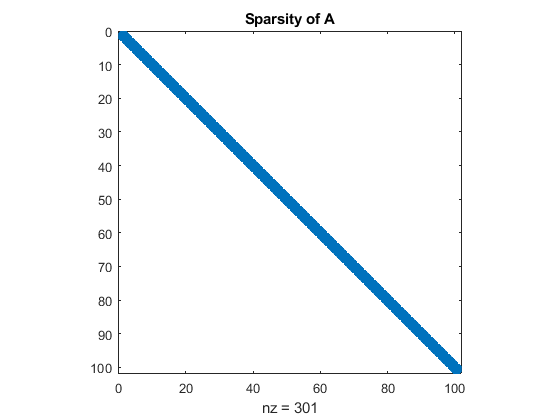

N = 101; % number of unknowns 
h = 1/(N+1); % step size 

% Construct matrix 
A = zeros(N,N);
for i = 1:N
    A(i,i) = -2*h^-2 + k^2;
    if (i>1)
        A(i,i-1) = h^-2;
    end
    if (i<N) 
        A(i,i+1) = h^-2;
    end
end

% Construct RHS 
x = (h:h:1-h)';
b = g(x);

spy(A) % take a look at matrix pattern
title('Sparsity of A')

The problem is now reduced to a linear system $A\;u=g\ldotp$ $A$ is just a tridiagonal. 

## Orthodir Algorithm 

Orthodir is a Krylov method which iteratively solves $Ax=b$ by constructing A-orthogonal search directions. 

The matrix $P=\left\lbrack p_1 ,\ldotp \ldotp \ldotp ,p_N \right\rbrack$, $N\times N$, stores the search directions in columns. 

The matix $R=\left\lbrack r_1 ,\ldotp \ldotp \ldotp ,r_N \right\rbrack ,N\times N$, stores the residual in columns. 


$$\mathrm{Step}\;0:\mathrm{let}\;r_1 =b\;\;\mathrm{and}\;\;p_1 =b$$



$$\textrm{Iterate}\;j=1,2,\dots ,N\;$$


    
$$\begin{array}{l}
\textrm{Step}\;1:\textrm{compute}\;A_{\textrm{proj}} =A\;p_j \\
\textrm{Step}\;2:\textrm{compute}\;\alpha_j =\frac{r_j \cdot A_{\textrm{proj}} }{A_{\textrm{proj}} \cdot A_{\textrm{proj}} }\\
\textrm{Step}\;3:\textrm{compute}\;\mu_j =\mu_{j-1} +\alpha_j \;p_j \\
\textrm{Step}\;4:\textrm{compute}\;r_{j+1} =r_j -\alpha \;A_{\textrm{proj}} \\
\textrm{Step}\;5:\textrm{Iterate}\;i=1\;\textrm{to}\;j
\end{array}$$


        
$${\textrm{Compute}\;\beta }_{\textrm{ij}} =\frac{-{\textrm{AA}}_{\textrm{proj}} \cdot A\;p_i }{A\;p_i \cdot A\;p_i }$$


    
$$\mathrm{Step}\;6:\mathrm{compute}\;p_{j+1} =A_{\mathrm{proj}} +\sum_{i=1}^j \beta_{\mathrm{ij}} p_i$$


The pros: 

- It's iterative and the number of iterations is << N

- It's a Krylov method, so it's guaranteed to find exact solution 

The cons: 

- Each search direction $p_j$ (length N) must be stored in memory for j = 1, 2, ... until convergence. 

tol = 1e-8;
APj  = zeros(N,N);
res  = zeros(N,N);
mu   = zeros(N,N);
P    = zeros(N,N);
beta = zeros(N,N);

% Step 0: r1 = b,  p1 = b
P(:,1) = b;
res(:,1) = b;

tic 
for j = 1:N
   
   %--------------Compute alpha_j
   APj(:,j) = A*P(:,j);
   alpha = dot(res(:,j),APj(:,j))/dot(APj(:,j),APj(:,j));
   
   if isnan(alpha)
       conv_iter = j; 
       break
   elseif (abs(alpha)<tol)
       conv_iter = j;
       break
   end
   
   %------ Compute mu_slow a solution
   mu(:,j+1) =  mu(:,j) + alpha*P(:,j);
   
   %------ Compute residual
   res(:,j+1) =  res(:,j) - alpha*APj(:,j);
       
   %----- Compute Beta_ij
   temp = A*APj(:,j);
   for i = 1:j
      beta(i,j) = -dot(temp,APj(:,i))/dot(APj(:,i),APj(:,i));
   end
   
   % ----- Compute next basis 
   P(:,j+1) = APj(:,j);
   for i = 1:j
      P(:,j+1) = P(:,j+1) + beta(i,j)*P(:,i);
   end
end
odirtime = toc;
res = res(:,1:conv_iter);
mu = mu(:,1:conv_iter);

## Result of Orthodir

We will go over the performance of the method. 

fprintf('Converged in %d iterations\n',conv_iter)

Converged in 3 iterations


The number of iterations is 3 << 101. 

tic
u = A\b;
btime = toc;
fprintf('Orthodir time:  %f\nBackslash time: %f\n',odirtime,btime)

Orthodir time:  0.015788
Backslash time: 0.010193


The solution time appears to be competitive with the backslash method. 

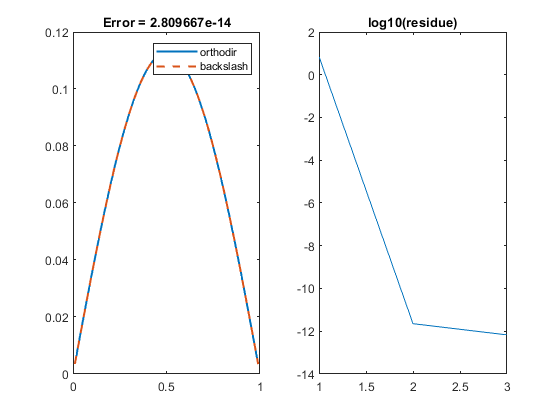

final_sol = mu(:,end);
subplot(121)
plot(x,final_sol,'linewidth',1.5)


hold on 
plot(x,u,'--','linewidth',1.5)
title(sprintf('Error = %e',norm(final_sol-u)/norm(u)))
legend('orthodir','backslash')
subplot(122)
plot(log10(vecnorm(res)))
title('log10(residue)')

The plot above shows that the orthodir solution matches up with the backslash solution. 

## Domain Decomposition 

The end goal is to use orthodir to solve $A\;u=g$ with orthodir preconditioned with DDM. Before that, we go over the ODDM in the form of a Jacobi iteration.

Let's split the domain into 2 parts, right down the middle. Let's extend the overlap at the center node by some integer number of nodes $\delta >0\ldotp$ 

Let's create a DDM matrix D. It will have this type of structure 

    
$$D=\left\lbrack \begin{array}{cc}
D_1  & 0\\
0 & D_2 
\end{array}\right\rbrack$$


where $D_1$ and $D_2$ are the local discretization of their interior nodes. The nodes near the middle are counted twice. 

Let's take for example $N=11$ and $\delta =1$. The global system is size 11, but each system $D_1$ and $D_2$ will have a size $N_{\mathrm{loc}} =\frac{N+1}{2}+\delta -1=6$. Therefore the DDM system $D$ is of size 12. There is 1 redundant node. In 1D, there are always $2\delta -1$ redundant nodes introduced. 

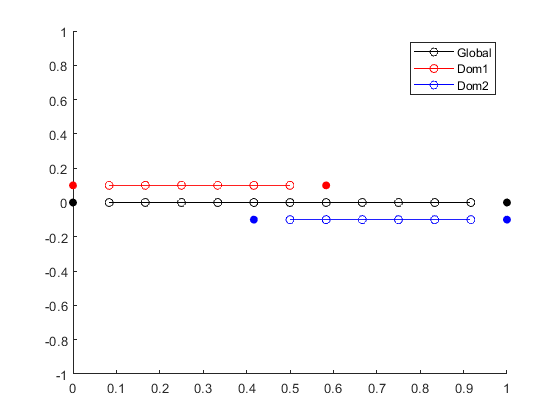

N = 11;
h = 1/(N+1);
x = h:h:1-h;
delta = 1;
Nloc = (N+1)/2+delta-1;
figure, hold on
p1 = plot(x,zeros(1,N),'ko-');
xlim([0,1])
plot(x(1:Nloc),zeros(1,Nloc)+0.1,'ro-')
plot(x(end-Nloc+1:end),zeros(1,Nloc)-0.1,'bo-')

scatter([0 1],[0 0],'ko','filled');
scatter([0 x((N+1)/2+delta)],[0 0]+0.1,'ro','filled');
scatter([x((N+1)/2-delta) 1],[0 0]-0.1,'bo','filled');
ylim([-1,1])
legend('Global','Dom1','Dom2')

The plot above shows the nodes for the global and local domains. The filled circles are the nodes which a Drichlet boundary condition is enforced. The local domains have a DBC on an interior global node. 

## Linear System for Jacobi

When we do the Jacobi block ddm iteration, the linear system will have the form:  

        
$$\left\lbrack \begin{array}{cc}
D_1  & 0\\
0 & D_2 
\end{array}\right\rbrack {\left\lbrack \begin{array}{c}
u_1 \\
u_2 
\end{array}\right\rbrack }^{\left(m\right)} =\left\lbrack \begin{array}{c}
g_1 \\
g_2 
\end{array}\right\rbrack +{\left\lbrack \begin{array}{c}
g_{12} \\
g_{21} 
\end{array}\right\rbrack }^{\left(m-1\right)}$$


The RHS vector contains 2 parts: the static part $\left\lbrack \begin{array}{c}
g_1 \\
g_2 
\end{array}\right\rbrack$ contains contribution from the source function $g\left(x\right)$ and the original Dirichlet conditions. 

The other vector ${\left\lbrack \begin{array}{c}
g_{12} \\
g_{21} 
\end{array}\right\rbrack }^{\left(m-1\right)}$changes with the each iteration based on the previous solution.

The discrete version of $u_1$ will obey 

        
$${u_1^{\prime } }^{\prime } \left(x_i \right)+k^2 u_1 \left(x_i \right)-g\left(x_i \right)\to \frac{1}{h^2 }\left({\mathrm{u1}}_{i+1} -2{\mathrm{u1}}_i +{\mathrm{u1}}_{i-1} \right)+k^2 {\mathrm{u1}}_i -g\left(x_i \right)$$


where ${{\textrm{u1}}_0 =0,\;\textrm{and}\;\textrm{u1}}_{N_{\textrm{loc}} +1} =u_2 \left(x_{12} \right)$. $u_2$ is similar with ${\textrm{u2}}_0 =u\left(x_{21} \right)$ and ${\textrm{u2}}_{N_{\textrm{loc}} +1} =0$.

We define the points $x_{\textrm{ij}}$ to be the boundary point of $\Omega_i$ which coincides with the boundary of $\Omega_j$, i.e. $x_{\textrm{ij}} =\bar{\Omega_i } \cap \partial \;\Omega_j$.

The Jacobi version of the iterative algorithm will proceed as follows: 

        
$$\begin{array}{l}
\mathrm{Step}\;0:\mathrm{Construct}\;D_1 \;\mathrm{and}\;D_2 \ldotp \mathrm{Construct}\;\mathrm{the}\;\mathrm{static}\;g_1 \;\mathrm{and}\;g_2 \\
\mathrm{Step}\;1:\mathrm{Factorize}\;D_1 \;\mathrm{and}\;D_2 \\
\mathrm{Iterate}\;m=1,2,\ldotp \ldotp \ldotp \mathrm{until}\;\mathrm{convergence}\;
\end{array}$$


                
$$\begin{array}{l}
\mathrm{Step}\;2:\mathrm{Construct}\;g_{12}^{\left(m\right)} \;\mathrm{and}\;g_{21}^{\left(m\right)} \;\mathrm{based}\;\mathrm{on}\;u_1^{\left(m-1\right)} \;\mathrm{and}\;u_2^{\left(m-1\right)} \\
\mathrm{Step}\;3:\mathrm{Solve}\;D_i u_i^{\left(m\right)} =g_i +g_{\mathrm{ij}}^{\left(m\right)} \;\mathrm{for}\;i=1,2
\end{array}$$


#### Construct the Ds and gs 

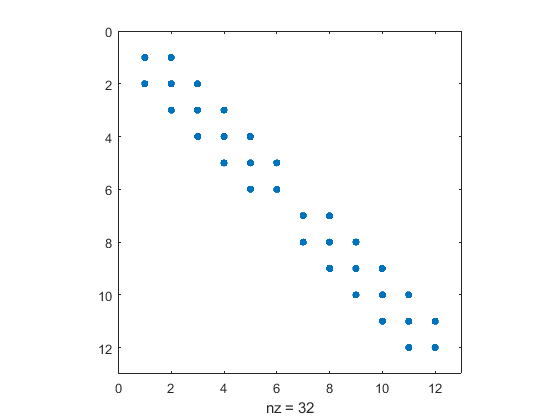

D1 = zeros(Nloc);
for i = 1:Nloc 
    D1(i,i) = -2*h^-2 + k^2;
    if (i>1)
        D1(i,i-1) = h^-2;
    end
    if (i<Nloc) 
        D1(i,i+1) = h^-2;
    end
end
D2 = D1; % they're actually the same 

x1 = x(1:Nloc)';
g1 = g(x1);
x2 = x(end-Nloc+1:end)';
g2 = g(x2);

D = blkdiag(D1,D2);
figure,spy(D) % peek at ODDM system

Normally, you would factorize the matrices but the systems are small. 

#### Initialize 

g12 = zeros(Nloc,1);
g21 = zeros(Nloc,1); 
u1 = zeros(Nloc,1);
u2 = zeros(Nloc,1);

#### Jacobi Iteration

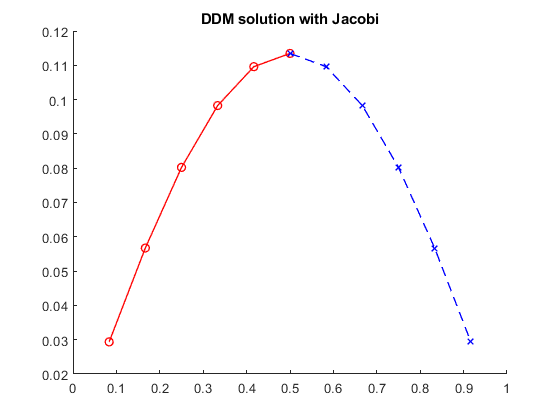

tol = 1e-8;
max_iter = 300; 

tic
for m = 1:max_iter 
    
    % update g12 using u2 
    g12(Nloc) = -u2(2*delta)/h^2;
    
    % update g21 using u1 
    g21(1) = -u1(Nloc-(2*delta)+1)/h^2;
    
    % solve local linear systems
    u1 = D1\(g1+g12);
    u2 = D2\(g2+g21);
    
    % residue
    ress = abs(g12(Nloc)+u2(2*delta)/h^2) + abs(g21(1)+u1(Nloc-(2*delta)+1)/h^2);
    if (ress < tol)
        conv_iter = m;
        break
    end    
end
jtime = toc;

figure, hold on
plot(x1,u1,'ro-',x2,u2,'bx--','linewidth',1)
title('DDM solution with Jacobi')

j_conv_iter = conv_iter

j_conv_iter = 68

jtime

jtime = 0.0202

 The Jacobi iteration has converged in 68 iterations at 0.019 seconds. 

## Domain Decomposition as a preconditioner for Orthodir

The orthodir algorithm can be applied to the domain decomposition problem instead of the Jacobi iteration and it usually converges much faster. 

Instead of thinking about an iteration of the local solutions $u^{\left(m\right)}$, you think of the DDM as an update of the boundary data, i.e, 

    $A\;{\left\lbrack \begin{array}{c}
g_{12} \\
g_{21} 
\end{array}\right\rbrack }^{\left(m\right)} ={\left\lbrack \begin{array}{c}
g_{12} \\
g_{21} 
\end{array}\right\rbrack }^{\left(m+1\right)} -\left\lbrack \begin{array}{c}
g_1 \\
g_2 
\end{array}\right\rbrack$, or 

    $A\;g^{\left(m\right)} =g^{\left(m+1\right)} +b$. 

The map$A$ is some operator that updates the Dirichlet data between each DDM iteration without the static RHS $b$. Note that the operator $A$ is not linear; it is expressed as a subroutine. 

We apply orthodir to the system $\left(I-A\right)\;\mu \;=g^{\left(0\right)}$. The vector $g^{\left(0\right)}$ cannot be zero. This vector is obtained by using the solution of $D\;y=b$. 

Once the orthodir iteration is complete, we use the $\mu \;$to solve 

    
$$\left\lbrack \begin{array}{cc}
D_1  & 0\\
0 & D_2 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
u_1 \\
u_2 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
g_1 \\
g_2 
\end{array}\right\rbrack +\mu \;$$


to get the final DDM solution. 

tol = 1e-16;
N = 2;
N_iters = 100;
APj  = zeros(N,N_iters);
res  = zeros(N,N_iters);
mu   = zeros(N,N_iters);
P    = zeros(N,N_iters);
beta = zeros(N,N_iters);

#### Preconditioned Orthodir

tic
% Solve once with the g(x) RHS
u1 = D1\(g1);
u2 = D2\(g2);

% construct rhs b 
b = zeros(2,1);
b(1) = -u2(2*delta+2)/h^2;
b(2) = -u1(Nloc-(2*delta+1))/h^2;

% Step 0: r1 = b,  p1 = b
P(:,1) = b;
res(:,1) = b;

% Begin orthodir iteration
for j = 1:N_iters
   
   %--------------Compute alpha_j
   APj(:,j) = A_projection(P(:,j),Nloc,h,delta,D1,D2);
   alpha = dot(res(:,j),APj(:,j))/dot(APj(:,j),APj(:,j));
   
   if isnan(alpha)
       conv_iter = j; 
       break
   elseif (abs(alpha)<tol)
       conv_iter = j;
       break
   end
   
   %------ Compute mu_slow a solution
   mu(:,j+1) =  mu(:,j) + alpha*P(:,j);
   
   %------ Compute residual
   res(:,j+1) =  res(:,j) - alpha*APj(:,j);
       
   %----- Compute Beta_ij
   temp = A_projection(APj(:,j),Nloc,h,delta,D1,D2);
   
   for i = 1:j
      beta(i,j) = -dot(temp,APj(:,i))/dot(APj(:,i),APj(:,i));
   end
   
   % ----- Compute next basis 
   P(:,j+1) = APj(:,j);
   for i = 1:j
      P(:,j+1) = P(:,j+1) + beta(i,j)*P(:,i);
   end
end

#### One last solve

% take the last result from orthodir and use it to construct rhs
g12 = zeros(Nloc,1); g12(Nloc) = mu(1,conv_iter);
g21 = zeros(Nloc,1);    g21(1) = mu(2,conv_iter);

% do one last solve with the static part 
u1 = D1\(g1+g12);
u2 = D2\(g2+g21);
oddmtime = toc

oddmtime = 0.0920

#### Result

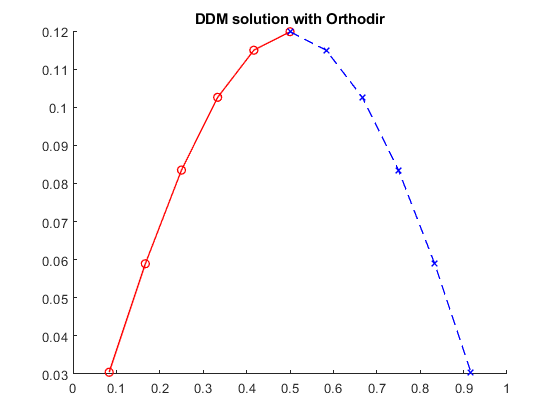

figure, hold on
plot(x1,u1,'ro-',x2,u2,'bx--','linewidth',1)
title('DDM solution with Orthodir')

[j_conv_iter; conv_iter]

ans =     68
    12


[jtime; oddmtime]

ans =     0.0202
    0.0920


#### The projection subroutine

Consider a DDM iteration that iteratively solves 

    
$$\left\lbrack \begin{array}{cc}
D_1  & 0\\
0 & D_2 
\end{array}\right\rbrack {\left\lbrack \begin{array}{c}
u_1 \\
u_2 
\end{array}\right\rbrack }^{\left(m\right)} ={\left\lbrack \begin{array}{c}
g_{12} \\
g_{21} 
\end{array}\right\rbrack }^{\left(m-1\right)} +\left\lbrack \begin{array}{c}
g_1 \\
g_2 
\end{array}\right\rbrack \ldotp$$


We recast this iteration in terms of the updating dirichlet data as 

    $A\left({\left\lbrack \begin{array}{c}
g_{12} \\
g_{21} 
\end{array}\right\rbrack }^{\left(m\right)} \right)={\left\lbrack \begin{array}{c}
g_{12} \\
g_{21} 
\end{array}\right\rbrack }^{\left(m+1\right)}$.

The function below is the operator $A$. 

function [Ap] = A_projection(p,Nloc,h,delta,D1,D2)
    
    % construct RHS without the static part
    g12 = zeros(Nloc,1);
    g21 = g12;
    g12(Nloc) = g12(Nloc) + p(1);
    g21(1)    = g21(1) + p(2);
    
    % solve system 
    u1 = D1\g12;
    u2 = D2\g21;
    
    % construct A*p  
    Ap = p; 
    Ap(1) = Ap(1) + u2(2*delta)/h^2;
    Ap(2) = Ap(2) + u1(Nloc-2*delta+1)/h^2;
end